# Plot Shear Force and Bending Moment Diagrams: 

## Testing with parameters from Ex. 7-2 (pg. 386)

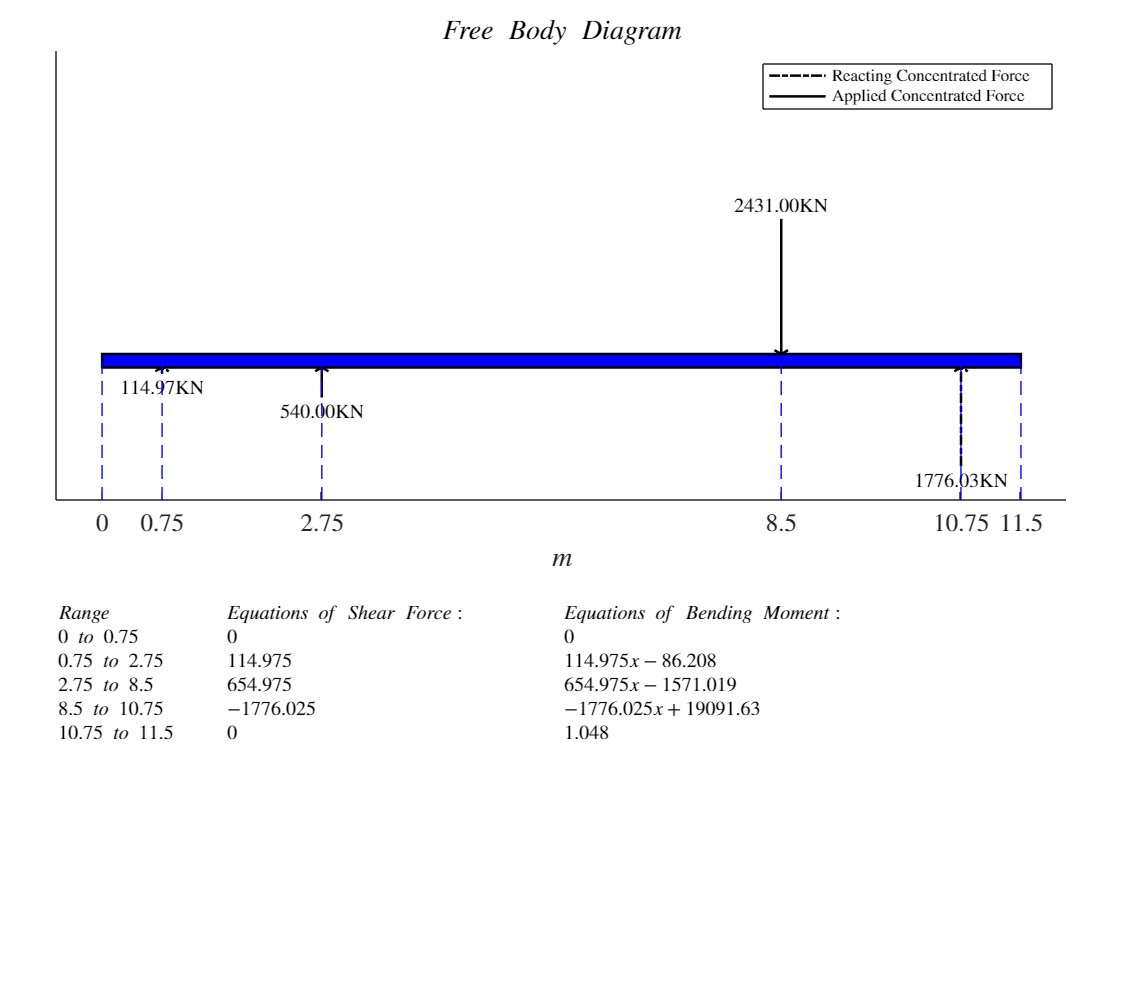

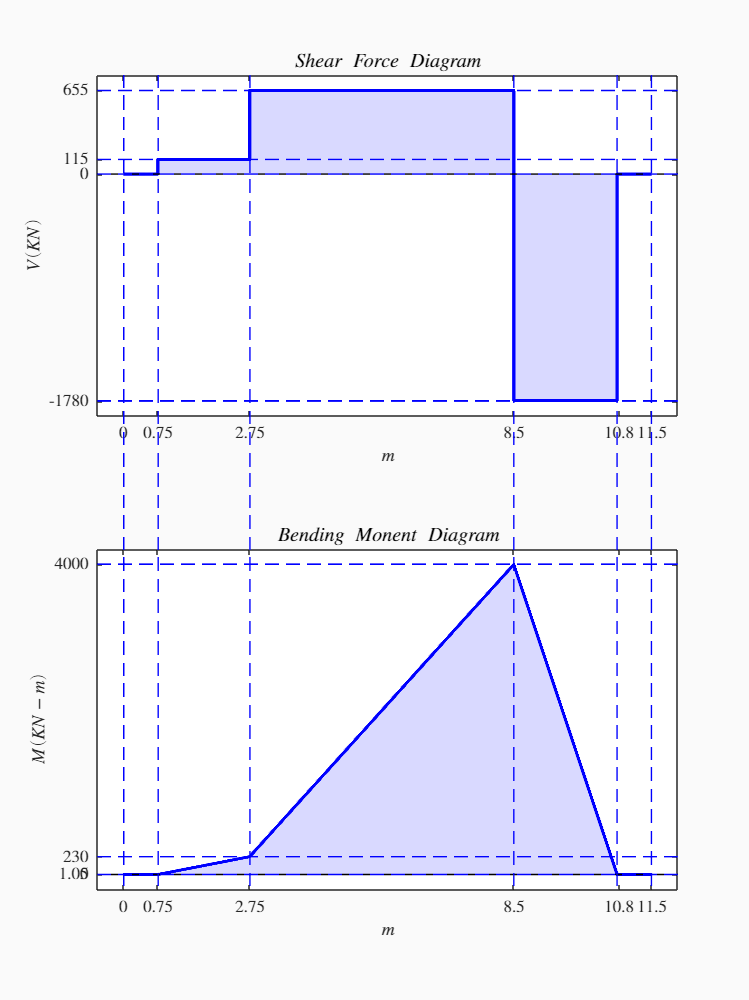

% Note: Requires a folder SFBM in this directory containing the extracted 
% script files from the link in Section 6 of the project manual:
% https://www.mathworks.com/matlabcentral/fileexchange/51047-shear-force-bending-moment

% Axial locations rightwards from the datum (left end of shaft) [in]
A = 0.75;       % Bearing A
B = 10.75;      % Bearing B
G = 2.75;       % Gear 3
J = 8.50;       % Gear 4
length = 11.50;

% Transmitted gear loads [lbf]
Wt_23 = 540;
Wr_23 = 197;
Wt_54 = 2431;
Wr_54 = 885;

SF_BM_diagrams(A,B,G,J, length, Wt_23,Wr_23,Wt_54,Wr_54);

## Function

function SF_BM_diagrams(A,B,G,J,length, Wt_23,Wr_23,Wt_54,Wr_54)
    addpath('SFBM');
    
    % Axial locations rightwards from the datum (left end of shaft)
    % See Fig. 7-10, pg. 386
    %   A: Bearing A
    %   B: Bearing B
    %   G: Gear 3
    %   J: Gear 4
    %   length: Overall length of shaft

    % Forces transmitted through gears (magnitudes - positive values):
    %   Wt_23
    %   Wr_23
    %   Wt_54
    %   Wr_54

    % Treat shaft as simply supported beam in xy- and xz-planes.

    % Problem Name
    Name_xz = 'xz-Plane';
    % Length and Supports
    LengthSupport_xz = [length,A,B]; % length  = 20m, supports at 5m and 20m;
    % Concentrated Loads
    load_Wt_23 = {'CF', Wt_23, G};
    load_Wt_54 = {'CF', -Wt_54, J};

    % Call the function to create the SF and BM diagrams
    % xz-Plane
    SFBM(Name_xz,LengthSupport_xz,load_Wt_23, load_Wt_54);

end